syms m k c x t zeta wp s x_undamped z(t) q(t)

% clear all
format bank
digits(3)

m=2;
k = 100;
c=2;
c_cr=sqrt(4*k*m)

c_cr =          28.28


wn=sqrt(k/m)

wn =           7.07


F0=1

F0 =           1.00


zeta=(c/c_cr)

zeta =           0.07



H=1/(m*s^2+c*s+k)

$$H = \frac{1}{2\,s^{2}+2\,s+100}$$

X=simplify(H*50/s*(1-exp(-5*s)));




x(t)=simplify(ilaplace(X)); 
x(t)= vpa(x,2)  % soluzione automatica di matlab

$$x(t) = 25.0\,\mathrm{heaviside}\left(1.0\,t-5.0\right)\,\left(0.02\,{\mathrm{e}}^{2.5-0.5\,t}\,\left(\cos\left(7.05\,t-35.3\right)+0.0709\,\sin\left(7.05\,t-35.3\right)\right)-0.02\right)-0.5\,{\mathrm{e}}^{-0.5\,t}\,\left(\cos\left(7.05\,t\right)+0.0709\,\sin\left(7.05\,t\right)\right)+0.5$$


y=0.5;

fplot(x,[0 10])                

hold on 

x(t)

$$ans = 25.0\,\mathrm{heaviside}\left(1.0\,t-5.0\right)\,\left(0.02\,{\mathrm{e}}^{2.5-0.5\,t}\,\left(\cos\left(7.05\,t-35.3\right)+0.0709\,\sin\left(7.05\,t-35.3\right)\right)-0.02\right)-0.5\,{\mathrm{e}}^{-0.5\,t}\,\left(\cos\left(7.05\,t\right)+0.0709\,\sin\left(7.05\,t\right)\right)+0.5$$

q(t)=vpa(0.5-0.5*exp(-0.5*t)*(cos(7.053*t)+0.0709*sin(7.053*t)),2) %%0-->5s quello che ho ottenuto su carta

$$q(t) = 0.5-0.5\,{\mathrm{e}}^{-0.5\,t}\,\left(\cos\left(7.05\,t\right)+0.0709\,\sin\left(7.05\,t\right)\right)$$

fplot(q,[0 5],'o-')

% q_dot = diff(q,t,1);

z(t)=vpa(-q(t-5)+q(t),2) %%5s-->10s quello che ho ottenuto su carta

$$z(t) = 0.5\,{\mathrm{e}}^{2.5-0.5\,t}\,\left(\cos\left(7.05\,t-35.3\right)+0.0709\,\sin\left(7.05\,t-35.3\right)\right)-0.5\,{\mathrm{e}}^{-0.5\,t}\,\left(\cos\left(7.05\,t\right)+0.0709\,\sin\left(7.05\,t\right)\right)$$

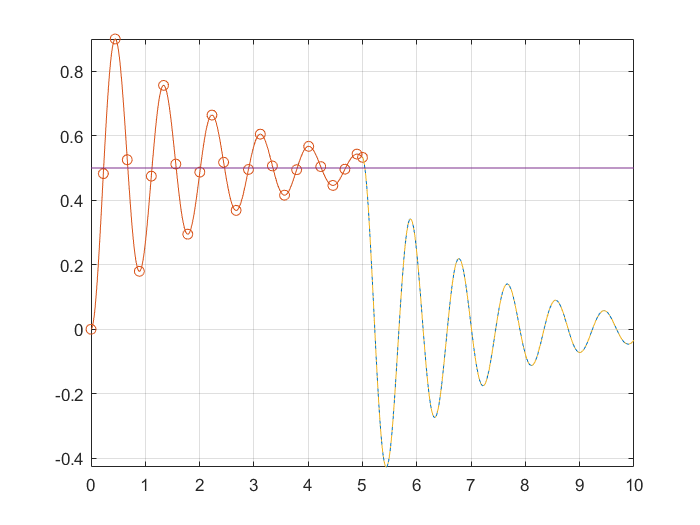

%% t>5s la heaviside(t) non si spegne ma si và a aggiungere ad heaviside(t-5)
fplot(z,[5 10],'-.')


fplot(y,[0 10])
grid on 
hold off